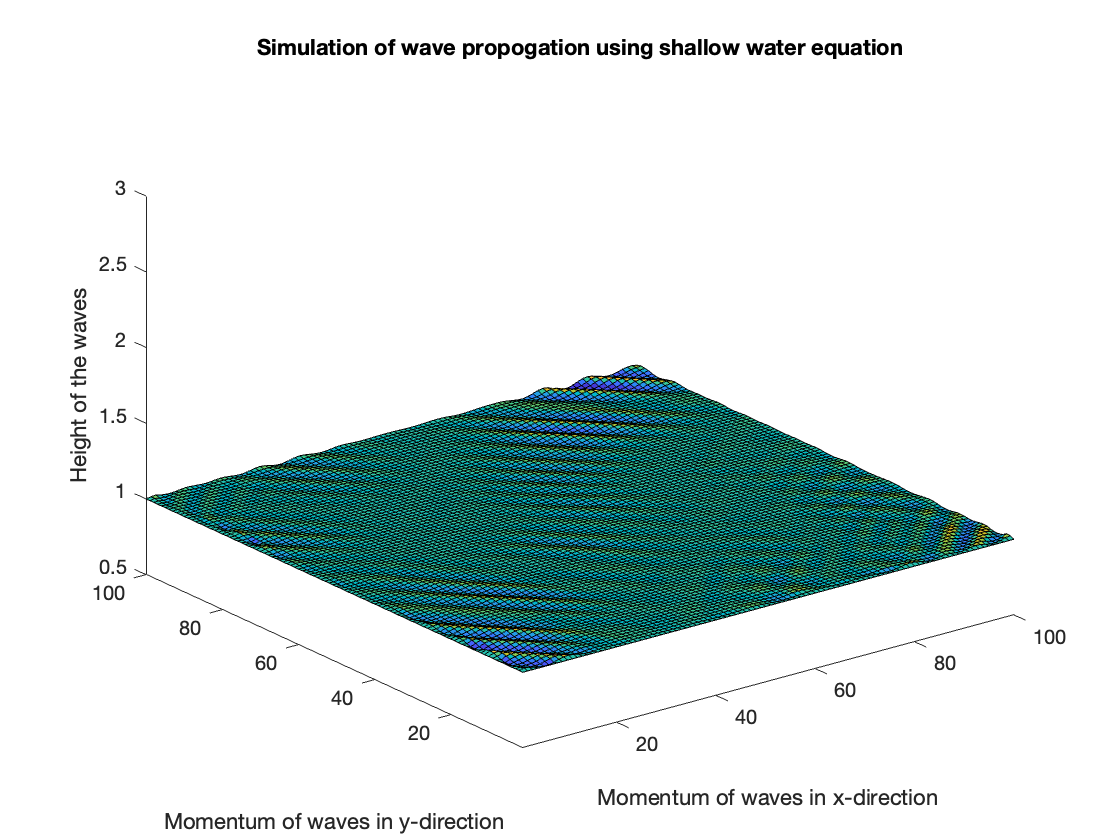

%------------------------------------------------
%Simmulation of Wave Propagation 
%using Shallow water Equations


%------------------------------------------------
    %Initial declarations
    
% Grid size of confined container
% define the grid size
n = 100;
dx = 0.1;
dy = 0.1;
%gravitational constant
g = 9.8;
%Timestep 
time = 0.009;
% Assuming flat topology for our model for initial condition
height = ones(n+2, n+2);
% Initialize the momentum in x and y directions
UXmomentum=zeros(n+2, n+2);
VYmomentum=zeros(n+2, n+2);
%Creating empty matrix for plotting, calculating momentums and storing
%values
Heightx = zeros(n+1,n+1);
Heighty = zeros(n+1,n+1);
Ux = zeros(n+1,n+1);
Uy = zeros(n+1,n+1);
Vx = zeros(n+1,n+1);
Vy = zeros(n+1,n+1);
[x,y] = meshgrid( linspace(-3,3,10) );
%---------------------------------------------------------------
            %Plot the initial displacement or droplet
            
%-------------------CASE 2---------------------------
%------------------Multiple Displacement-------------

% create initial displacement or disturbance of water(droplet)
height(2:5,5:10) = height(2:5,5:10) + 1;
height(25:35,35:45) = height(25:35,35:45) + 1;
height(60:70,70:80) = height(60:70,70:80) + 1;
% Plot initial displacement
graph = surf(height);
axis([1 n 1 n 0.5 3]);
%colormap winter;
%shading interp;
hold all;
%plot the momentums and height of water
     title("Simulation of wave propogation using shallow water equation - multiple displacement");
     set(graph, 'zdata', height);
     xlabel("Momentum of waves in x-direction");
     ylabel("Momentum of waves in y-direction");
     zlabel("Height of the waves");


%Using the Conservative equation for wave propogation
for t=1:1000
    
            
     %Boundary condition 1 - Lax-Wendroff equation half step calculation
     p = 1:n+1;
     q = 1:n+1;
    
     % height in x and y directions
     Heightx(p,q) = (height(p+1,q+1)+height(p,q+1))/2 - ...
                time/(2*dx)*(UXmomentum(p+1,q+1)-...
                UXmomentum(p,q+1));
     Heighty(p,q) = (height(p+1,q+1)+height(p+1,q))/2 - ...
               time/(2*dy)*(VYmomentum(p+1,q+1)-...
               VYmomentum(p+1,q));
    
     % waves in x and y direction/momentum 
     Ux(p,q) = (UXmomentum(p+1,q+1)+UXmomentum(p,q+1))/2 - ...
               time/(2*dx)*(UXmomentum(p+1,q+1).^2./height(p+1,q+1) - ...
               UXmomentum(p,q+1).^2./height(p,q+1) + ...
               g/2*height(p+1,q+1).^2 - g/2*height(p,q+1).^2);
     
     Uy(p,q) = (UXmomentum(p+1,q+1)+UXmomentum(p+1,q))/2 - ...
               time/(2*dy)*( (VYmomentum(p+1,q+1).*UXmomentum(p+1,q+1)./height(p+1,q+1)) - ...
               (VYmomentum(p+1,q).*UXmomentum(p+1,q)./height(p+1,q)) );
     Vx(p,q) = (VYmomentum(p+1,q+1)+VYmomentum(p,q+1))/2 - ...
                time/(2*dx)*((UXmomentum(p+1,q+1).*VYmomentum(p+1,q+1)./height(p+1,q+1)) - ...
                (UXmomentum(p,q+1).*VYmomentum(p,q+1)./height(p,q+1)));
    
     Vy(p,q) = (VYmomentum(p+1,q+1)+VYmomentum(p+1,q))/2 - ...
                time/(2*dy)*((VYmomentum(p+1,q+1).^2./height(p+1,q+1) + ...
                g/2*height(p+1,q+1).^2) - (VYmomentum(p+1,q).^2./height(p+1,q) + ...
                g/2*height(p+1,q).^2));
    
     %Boundary condition2  
     p = 2:n+1;
     q = 2:n+1;

     % height in x and y direction
     height(p,q) = height(p,q) - (time/dx)*(Ux(p,q-1)-Ux(p-1,q-1)) - (time/dy)*(Vy(p-1,q)-Vy(p-1,q-1));
     
     % x-axis momentum 
     UXmomentum(p,q) = UXmomentum(p,q) - (time/dx)*((Ux(p,q-1).^2./Heightx(p,q-1) + g/2*Heightx(p,q-1).^2) - ...
              (Ux(p-1,q-1).^2./Heightx(p-1,q-1) + g/2*Heightx(p-1,q-1).^2)) ...
               - (time/dy)*((Vy(p-1,q).*Uy(p-1,q)./Heighty(p-1,q)) - ...
              (Vy(p-1,q-1).*Uy(p-1,q-1)./Heighty(p-1,q-1)));
     
     % y-axis momentum
     VYmomentum(p,q) = VYmomentum(p,q) - (time/dx)*((Ux(p,q-1).*Vx(p,q-1)./Heightx(p,q-1)) - ...
              (Ux(p-1,q-1).*Vx(p-1,q-1)./Heightx(p-1,q-1))) ...
              - (time/dy)*((Vy(p-1,q).^2./Heighty(p-1,q) + g/2*Heighty(p-1,q).^2) - ...
              (Vy(p-1,q-1).^2./Heighty(p-1,q-1) + g/2*Heighty(p-1,q-1).^2));
     
     % plot the momentums and height of water
     title("Simulation of wave propogation using shallow water equation");
     set(graph, 'zdata', height);
     xlabel("Momentum of waves in x-direction");
     ylabel("Momentum of waves in y-direction");
     zlabel("Height of the waves");
     grid off;
     drawnow
           
end